# Solving Ordinary Differential Equations

## Preliminaries

Let's go through some examples of solving Initial Value Problems in Matlab.  For all the solvers used, the equations must be in first-order form.


$$\dot x = f(t,x)$$


Where $x$ is the list of states.  If we have a system like a good-old oscillator (which happens to be a 2nd order differential equation)


$$m \ddot x + c \dot x + k x = h(t)$$


We would pick some states, and rewrite the system in the required form.  I'll choose


$$x_1 = x\\x_2 = \dot x$$


Using those definitions and the given equation from before, I can rearrange things to get the following two equations


$$\dot x_1 = x_2 \\
\dot x_2 = -\frac{k}{m}x_1 - \frac{c}{m}x_2 + \frac{1}{m} h(t)$$


It does not matter, for the solvers considered here, if the equation is linear or not.  This one happens to be, but that's not important.  I can write the above expression as either a function, or an annonymous function.  Since this one is small, I choose to use an annymous function.  Also, I'll pick some example values for the paramters of the system.

m = 1;  % [slug]
c = 1;  % [lbf s/ft]
k = 10; % [lbf/ft]
h = @(t) sin(2*t).*exp(-0.5*t);

f = @(t,x) [x(2);
    -k/m*x(1) - c/m*x(2) + h(t)/m];

## ode45

The standard ode solver for non-stiff IVP's is `ode45`.  It's an adaptive-step Runge-Kutta based solver, that usually works pretty well.  There are ocasions it will fail (sometime suitbely, sometimes spectacularly).  But it's the best place to start.

The inputs to any of the ode solvers in matlab are

- `f(t,x)`: The ode system (in 1st order form) as a function of input arguments `(t,x)`.  t is time, and x are the states.  I'll have an example below about passing in extra parameters.

-  `tspan`: the time that you want to integrate.  This can either be in the form `[ti,tf]` or it can be an entire list of time values.  The outputs of the ode solver will change depending on which form of tspan is used.  Changing tspan does not change anything about what the solver does to solve the problem (like take a small time step), it only changes where we get interpolated values of the solution.

- `x0`: the list of initial conditions for the problem.  This must have the same number of entries as there are states in the system.

Getting back to the example, I'll define some initial conditions and a time-span to integrate.

tspan = linspace(0,10,100);
x0 = [1;-1];
[t,x] = ode45( f, tspan, x0 );

That's it, we've integrated the equation.  This is usually the part where we want to view the results in a plot.  So I'll do that.

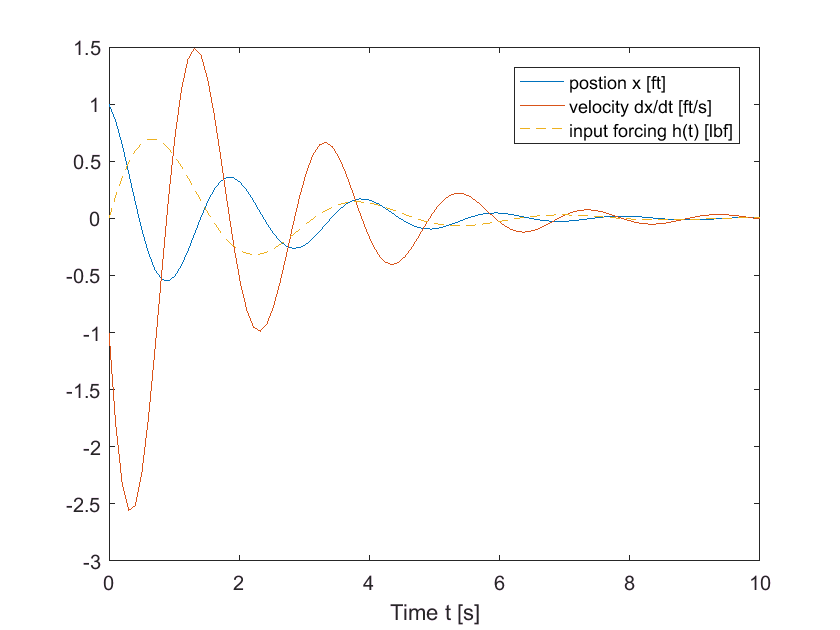

figure
plot(t,x)
hold on
plot(t, h(t),'--')
legend('postion x [ft]', 'velocity dx/dt [ft/s]', 'input forcing h(t) [lbf]')
xlabel('Time t [s]')

## Another example

Another example is provided as a script and function.